QEA Final Project

Fisher Faces

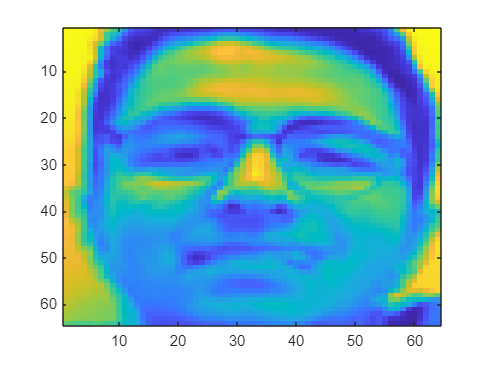

clear

load class_data_test.mat
load class_data_train.mat

% reshape images to 2d matrix - 4096x356 (4096 pixels, 356 faces)
trainfaces = reshape(grayfaces_train, size(grayfaces_train,1)*size(grayfaces_train,2),size(grayfaces_train,3));

% find the mean of each class - each class is a different subject/person
numclasses = max(subject_train);
meanclass = zeros(4096, numclasses); % 4096x89
j = 0;
temp = zeros(4096,1);
num = 1;
for i = 1:size(trainfaces, 2)
    if subject_train(i) == num
        j = j + 1;
        temp = temp + trainfaces(:,i);
    else
        meanclass(:,num) = temp/j;
        temp = trainfaces(:,i);
        j = 1;
        num = num + 1;
    end
end
meanclass(:,num) = temp/j; % for the last subject

% making sure meanclass works
testimage = reshape(meanclass(:,1), 64, 64);
imagesc(testimage(:,:))

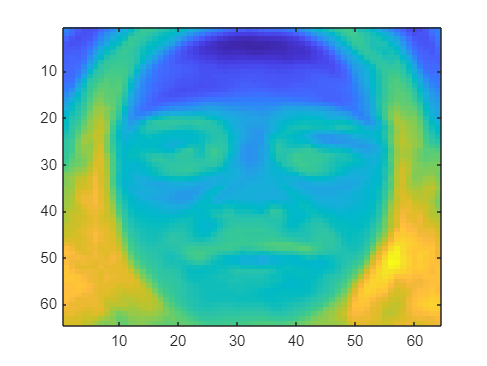


% find scatter within classes
swithin = zeros(4096, 4096);
j = 1;
for i = 1:size(trainfaces, 2)
    if j == subject_train(i)
        inside = (trainfaces(:,i) - meanclass(:,j))*transpose(trainfaces(:,i) - meanclass(:,j));
        swithin = swithin + inside;
    else
        j = j + 1;
        inside = (trainfaces(i) - meanclass(:,j))*transpose(trainfaces(:,i) - meanclass(:,j));
        swithin = swithin + inside;
    end
end


% find scatter between classes
sbetween = zeros(4096);
for i = 1:numclasses
    inside = (meanclass(i) - mean(trainfaces, 2))*transpose(meanclass(i) - mean(trainfaces, 2));
    inside = inside * numclasses;
    sbetween = sbetween + inside;
end

[pca_vectors,pca_eigs]=eigs(cov(trainfaces')); % W_pca
[vectors, diag] = eigs(pca_vectors'*sbetween*pca_vectors, pca_vectors'*swithin*pca_vectors); %W_fld
w_opt = (vectors'*pca_vectors')';

testimage = reshape(w_opt(:,2), 64, 64);
imagesc(testimage(:,:))